#  034IN "Fundamentals of Automatic Control" - Introduction to MATLAB

#  State Space Descriptions: Criteria and Examples

## Introduction

This live script uses MATLAB to implement a state space description for some dynamic (linear or nonlinear, time-invariant or time-variant, continuous time) systems.

What you will learn: 

- Given a state space description of a dynamic system, how to build a MATLAB model for such a system;

- Tune a MATLAB model, setting the model parameters (or the simulation parameters) using the command `ode`;

- How to simulate a MATLAB model of a dynamic system, and retrieve the results using the MATLAB command `solve`.

## First Example: Model Based on Conservation Balances

The dynamics of the system is given by the state-space model derived from conservation balances (of mass, energy, etc.).

### A Nonlinear Continuous Time System: a Bio-Reactor

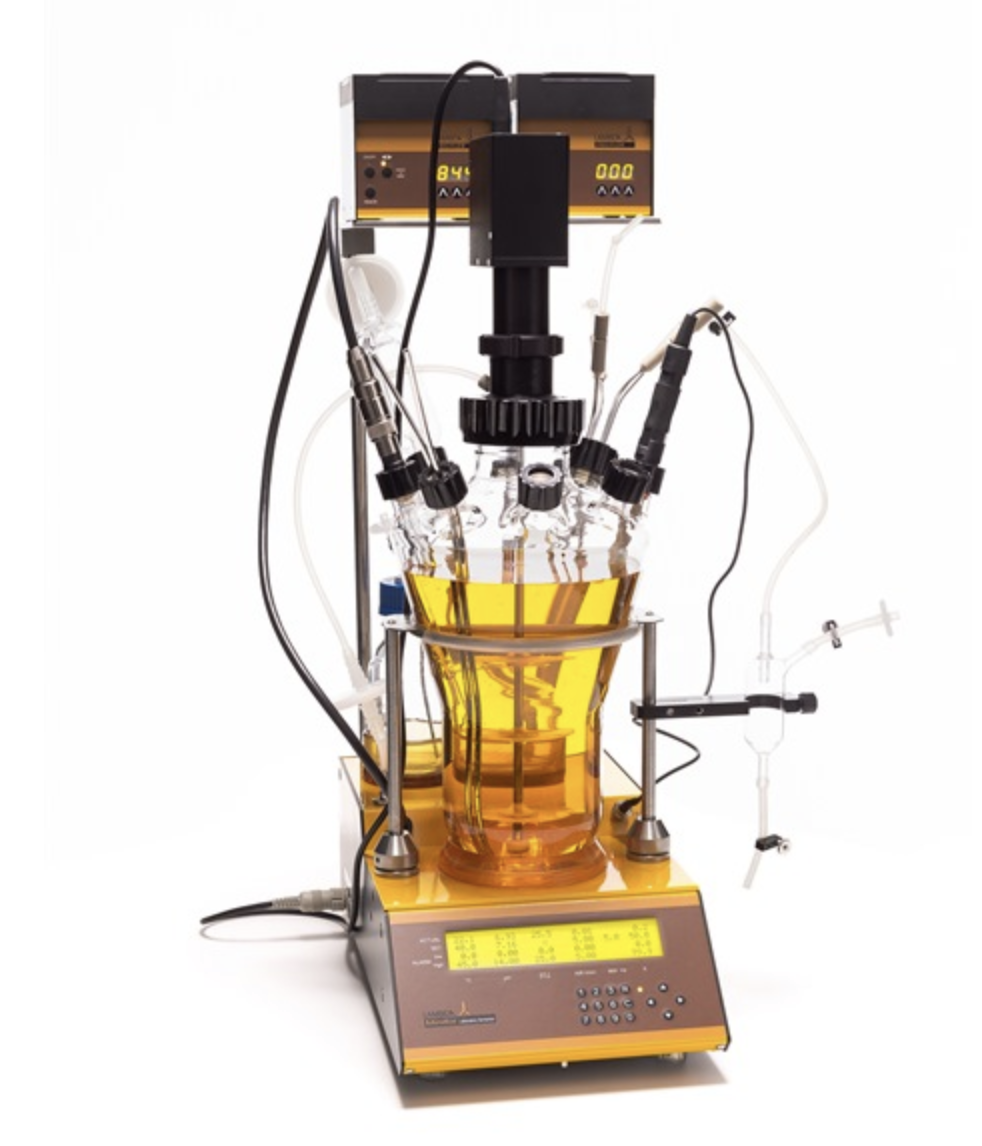

Example of fermenter-bioreactor (Source: LAMBDA Instruments)

The dynamics of the process are derived from the conservation balances for the biomass with concentration $x_1$and substrate mass with concentration $x_2$


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& \mu \left( x_2(t) \right) \cdot x_1(t) - \displaystyle \frac{x_1(t) \cdot  u(t)}{V} \\[0.5em]
\dot{x}_2(t) &=& -\displaystyle \frac{\mu\left( x_2(t) \right) \cdot x_1(t)}{Y} + \frac{\left(S_{F}-x_2(t)\right) \cdot u(t)}{V} \\[0.5em]
y_1(t) &=& x_1(t) \\[0.5em]
y_2(t) &=& x_2(t) 
\end{array} \right. \quad \text{where} \qquad \mu\left(x_2(t)\right) = \mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2 x_2^2(t) + x_2(t)+K_1}$$


where

- $x_1$ is the biomass concentration [g/l];

- $x_2$ is the substrate concentration [g/l];

- $u$ is the feed flow rate [l/h]

and the parameters assume the following values

- volume $V$:  $V= 4 \; \text{[l]}$

- substrate feed concentration $S_F$: $S_{F} = 10 \; \text{[g/l]}$

- yield coefficient $Y
$: $Y = 0.5 \; \text{ [-]}$

- maximal grow rate $\mu_{\text{max}}$: $\mu_{\text{max}} = 1 \; \text{[l/h]}$

- saturation parameter $K_1$: $K_1 = 0.03 \; \text{[g/l]}$

- inhibition parameter $K_2$: $K_2 = 0.5 \; \text{[l/g]}$

Finally, the initial condition for the bioreactor corresponds to the following values for the state variables:


$$\begin{array}{rcl}
x_{2}(0) &=& -\displaystyle \frac{\left[K_1 - \sqrt{K_1\, \left(K_2\,S_F^2 + S_F + K_1 \right)}\, \right] }{\big(K_2\,S_F + 1 \big)} = x_{2,0} \\
x_1(0) &=&\big(S_F-x_{2,0} \big)\,Y = x_{1,0} 
\end{array}$$


and the input $u(t)$ is defined as follows


$$\begin{array}{rcl}
u(t) &=& \Big\{U_M+u_A \cdot \Big[ \sin \big( 2\pi\,f_U\,t \big) \Big] \Big\}\cdot 1(t) \\
U_M &=& V\,\mu_{\text{max}}\,\frac{x_{2,0}}{K_2\,x_{2,0}^2+x_{2,0}+K_1} \;\text{[l/h]}\\
u_A &=& 0.75\cdot 10^{-3} \;\text{[l/h]}\\
f_U &=&  \frac{1}{t_U}\;,\qquad t_U = 2.5 \;\text{[h]}
\end{array}$$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


#### Cleaning the MATLAB Workspace

close all
clear
clc


#### Assigning the System Parameters

V = 4;     % volume [l]
S_F = 10;  % substrate feed concentratiion [g/l]
Y = 0.5;   % yield coefficient
muMAX = 1; % maximal grow rate [l/h]
K1 = 0.03; % saturation parameter [g/l]
K2 = 0.5;  % inhibition parameter [g/l]

#### Initial Condition and Input Configuration

x2_0 = -(K1 - (K1*(K2*S_F^2 + S_F + K1))^(1/2))/(K2*S_F + 1); % initial substrate concentration [g/l]
x1_0 =(S_F-x2_0)*Y;                                           % initial biomass concentration [g/l]

U_M = V*muMAX*x2_0/(K2*x2_0^2+x2_0+K1);   % mean input flow rate [l/h]
                                     
u_A = 0.75e-3;    % amplitude of the sinusoidal wave input component [l/h]
T_u = 2.5 * 3600; % time period of the periodic input component [seconds]


#### Simulation Time Interval

T_start = 0.0;        % starting time instant
T_stop = 10.0 * 3600; % end of the simulation after 10 h

### Solving an Ordinary Differential Equation in MATLAB

The dynamic model of the bioreactor is a **system of two first-order Ordinary Differential Equations (ODEs)**. 


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& \mu \left( x_2(t) \right) \cdot x_1(t) - \displaystyle \frac{x_1(t) \cdot  u(t)}{V} \\[0.5em]
\dot{x}_2(t) &=& -\displaystyle \frac{\mu\left( x_2(t) \right) \cdot x_1(t)}{Y} + \frac{\left(S_{F}-x_2(t)\right) \cdot u(t)}{V} \\[0.5em]
y_1(t) &=& x_1(t) \\[0.5em]
y_2(t) &=& x_2(t) \\
u(t) &=& \Big\{U_M+u_A \cdot \Big[ \sin \big( 2\pi\,f_U\,t \big) \Big] \Big\} \cdot 1(t)\\
\end{array} \right. \quad \text{where} \qquad \mu\left(x_2(t)\right) = \mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2 x_2^2(t) + x_2(t)+K_1} \qquad (\star)$$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


#### **Important Remark**

 The order of the ODE equations is crucial: to be able to solve numerically in MATLAB a system of ODEs of order $n$ (with $n \ge 1$), we must always rewrite the $n$-th order ODEs set as a system of first-order ODEs, properly coupled each to the others. Once we have obtained the set of first-order ODEs, we can describe this set using the MATLAB command `ode`.

#### The MATLAB Command ode

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a (vectorial) function (the solution of the ODE we are looking for) and $p$ is a vector of parameters.

Thus, since the ODEs $(\star)$ are already a set of first-order ODEs (nonlinear ODEs), we can describe the ODEs set structure using the command `ode.`

#### Important Remark on Notation

It's not mandatory to obey the notation $\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$. Indeed, we will use a different notation for  IPVs, when they describe the evolution of a dynamic system (linear or nonlinear), keeping the notation $x$ for the state variables (the variables affected by the ODEs), and using the notation $y$ for the system's outputs. Thus, our default notation for an IVP is


$$\dot{x}(t) = f\big(t,\,x(t), p \big)\,,\quad \dot{x}(t) = \frac{d\,x(t)}{dt}$$


**Putting the ODEs in MATLAB**: Let's define the system of first-order ODEs with given initial conditions in MATLAB, using the command `ode`


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& \left[\mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2\, x_2^2(t) + x_2(t)+K_1} \right] \cdot x_1(t) - \displaystyle \frac{x_1(t) \cdot  u(t)}{V} \\[0.5em]\\
\dot{x}_2(t) &=& -\displaystyle \frac{\left[\mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2 \,x_2^2(t) + x_2(t)+K_1} \right] \cdot x_1(t)}{Y} + \frac{\left(S_{F}-y_2(t)\right) \cdot u(t)}{V} \\[0.5em]\\
x_1(0) &=& x_{1,0} \\[0.5em]
x_2(0) &=& x_{2,0} \\
u(t) &=& \Big\{U_M+u_A \cdot \Big[ \sin \big( 2\pi\,f_U\,t \big) \Big] \Big\} \cdot 1(t)\\
\end{array} \right. $$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


%
BioR_ODE = ode;                                  % let's initialise an ODE object
BioR_ODE.Parameters   = [V, S_F, Y, muMAX, ...
                         K1, K2, U_M, u_A, T_u];  % the parameters of the differential equation
% V = 4;     % volume [l]
% S_F = 10;  % substrate feed concentratiion [g/l]
% Y = 0.5;   % yield coefficient
% muMAX = 1; % maximal grow rate [l/h]
% K1 = 0.03; % saturation parameter [g/l]
% K2 = 0.5;  % inhibition parameter [g/l]

BioR_ODE.InitialValue = [x1_0, x2_0];  % the initial conditions
BioR_ODE.InitialTime = T_start;        % starting time instant
                                       % the initial time instant of the solution, where 
                                       % the initial conditions are applied
BioR_ODE.ODEFcn = @BioreactorODE;  % BioreactorODE is the MATLAB function describing the ODE, 
                                % we would like to solve. 
                                % The code of BioreactorODE is at the end
                                % of this live script.

#### Simulation of the System - Solving the ODE

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

For help on using the command `solve`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `solve` command computes the solution of the considered IVP `F` in the time interval `[t0, tf]`, returning the solution `S` at each time step chosen by the solver: 


S  = solve(BioR_ODE, T_start, T_stop); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

bioreactor_x = S.Solution; % the result of the IPv
t_stamps = S.Time;   % time instants corresponding to the solution samples 

bioreactor_x1 = bioreactor_x(1,:);
bioreactor_x2 = bioreactor_x(2,:);

y1 = bioreactor_x1; % the model output y_1
y2 = bioreactor_x2; % the model output y_2
u = U_M+u_A*sin((2*pi)*(t_stamps/T_u));  % the input u <-- NOTE: We are forced to recalculate the input 

t_stamps = t_stamps/3600; % time instants [h]
% time instants corresponding to the solution samples 

#### Retrieving and Showing the Result

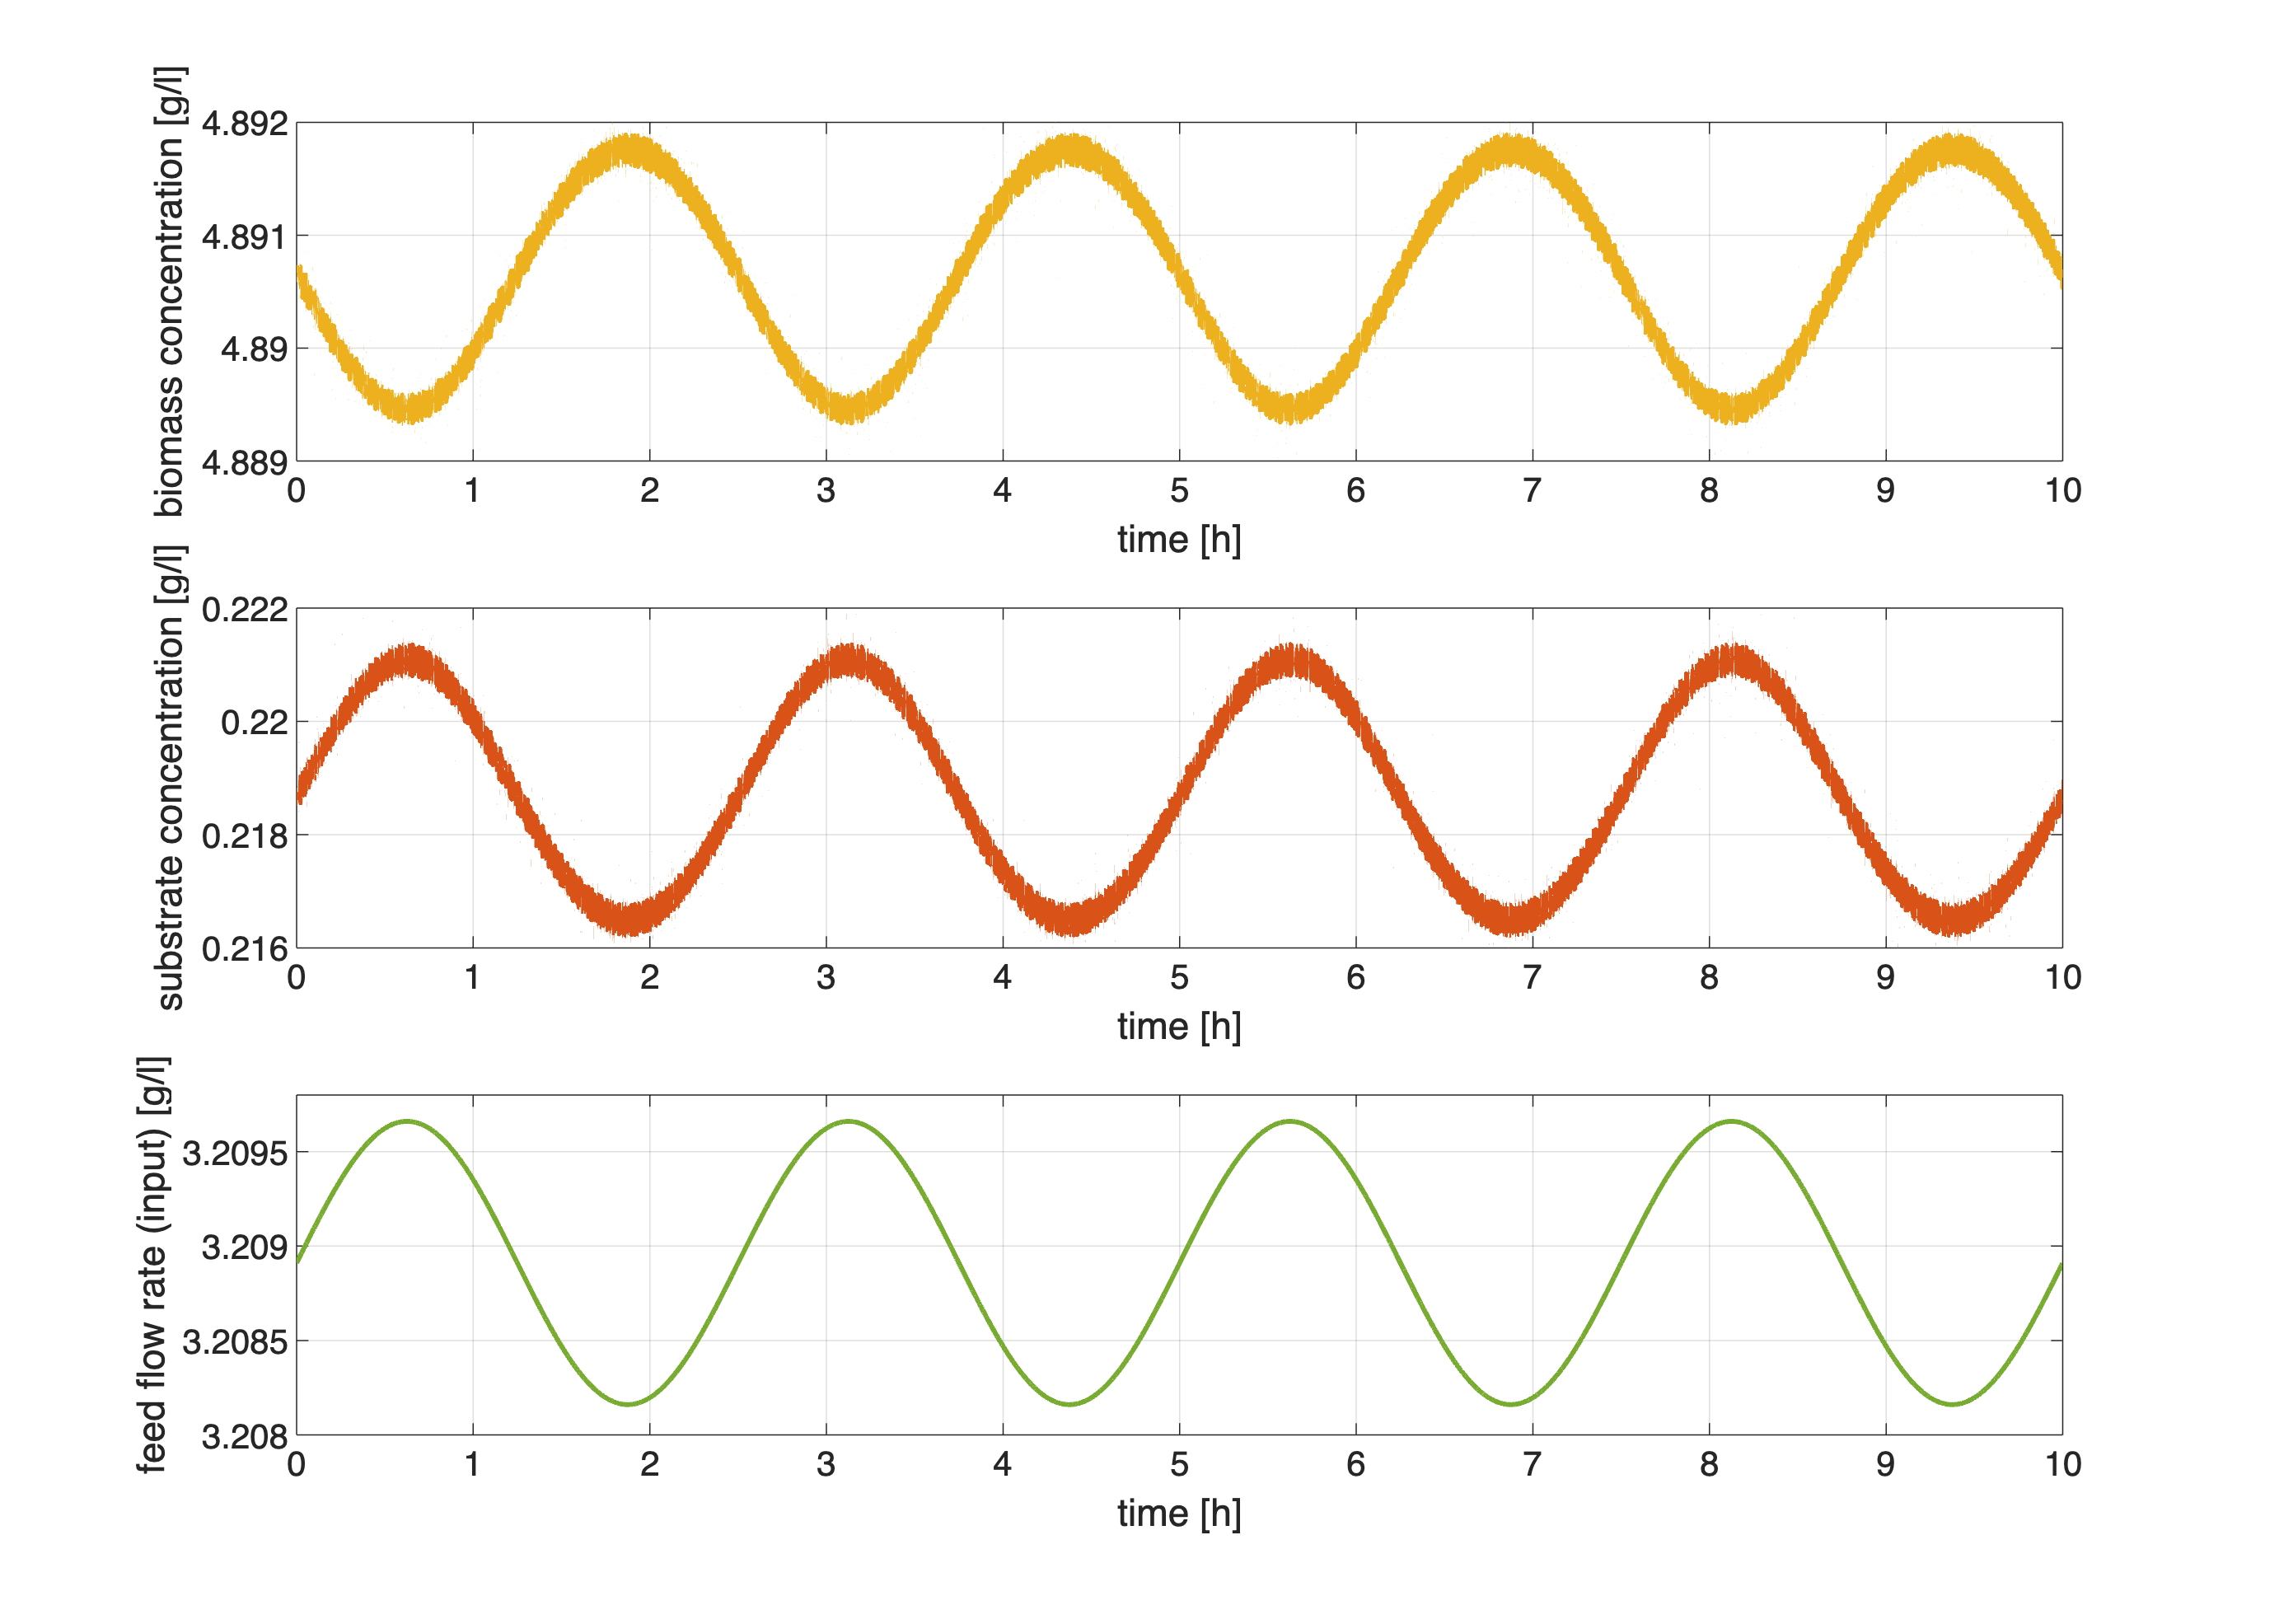

figure('Name','Bioreactor Simulation','Units','normalized','Position',[0.1, 0.1, 0.75, 0.95]);
h1 = subplot(3,1,1);
plot(t_stamps, y1, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]); % bioreactor outputs y_1 vs time
xlabel('time [h]'); ylabel('biomass concentration [g/l]'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);

h2 = subplot(3,1,2);
plot(t_stamps, y2, 'LineWidth',2, 'Color',[0.8500 0.3250 0.0980]); % bioreactor outputs y_2 vs time
xlabel('time [h]'); ylabel('substrate concentration [g/l]'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);

h3 = subplot(3,1,3);
plot(t_stamps, u, 'LineWidth',2, 'Color',[0.4660 0.6740 0.1880]); % bioreactor outputs y_2 vs time
xlabel('time [h]'); ylabel('feed flow rate (input) [g/l]'); % labels on the plot axes
grid on;currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);

linkaxes([h1 h2 h3], 'x');

## Second Example: Model Based on Input-Output Mathematical Description

The state-space model is derived from an input/output model based on differential equations or from an in-out difference equation model.

### A Nonlinear Continuous Time System: a Second Order Ordinary Differential Equation

Let us consider the nonlinear dynamical system defined by the differential equation


$$\ddot{y}(t) +\alpha_1 \dot{y}(t) +\alpha_0 y(t)\cdot \left[1+\gamma_1 y^{2}(t)\right] = \beta_0 \left[ 1+\gamma_2 y(t) \right] \cdot u(t) \qquad (*)$$


This model can be expressed in state-space form as


$$\left\{\begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\[0.5em]
\dot{x}_2(t) 
\end{array} \right] &=& \left[ \begin{array}{c}
x_2(t) \\[0.5em]
f\left(x_1(t)\,,\; x_2(t)\,,\; u(t)\right) 
\end{array} \right] \\[0.75em]
y(t) &=& x_1(t)
\end{array} \right. $$


where


$$f\left(x_1(t)\,,\; x_2(t)\,,\; u(t) \right) = -\alpha_1 x_2(t) -\alpha_0 x_1(t)\cdot \left[1+\gamma_1 x_1^2(t) \right] +\beta_0 \left[1+\gamma_2 x_1(t)\right]\cdot u(t)$$


by assuming


$$x_1(t):= y(t) \qquad x_2(t) := \dot{y}(t) = \dot{x}_1(t)$$


#### Parameters

Assume the following values for the differential equation parameters:

- 
$$\alpha_1 = 3\,,\; \alpha_0 = 2\,,\; \gamma_1 = 0.5$$


- 
$$\beta_0 = 2\,,\; \gamma_2 = 0.25$$


#### Initial values

Moreover, the initial values for the state variables are

- 
$$x_1(0) = y(0) = +2.50$$


- 
$$x_2(0) = \dot{y}(0) = -24.48$$


#### Input

Apply as input $u(t)$ the following signal:


$$u(t) = e^{-4\,t}\cdot \left[2.50 \sin(3\,t)-7.25 \cos(2\,t) \right]\cdot 1(t)$$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


### Cleaning the MATLAB Workspace

close all
clear
clc


### Assigning the System Parameters

alpha1 = 3.0;  %#ok<*NASGU> 
alpha0 = 2.0;  
gamma1 = 0.5;  
beta0 = 2.0; 
gamma2 = 0.25; 

#### Initial Condition and Input Configuration

x1_0 =  +2.50; % initial value of the 1st state variable
x2_0 = -24.48; % initial value of the 2nd state variable

u_expT = 1/4;  % time constant of the exponential input component
u_sinA = 2.50; % amplitude of the sinusoidal input component
u_sinO = 3.0;  % angular frequency of the input sinusoidal component [rad/s]
u_cosA = 7.25; % amplitude of the cosinusoidal input component
u_cosO = 2.0;  % angular frequency of the input cosinusoidal component [rad/s]


#### Simulation Time Interval

T_start2 = 0.0; % starting time instant [s]
T_stop2 = 5.0; % end of the simulation  [s]

### Solving the ODE in MATLAB

By exploiting the definitions


$$x_1(t):= y(t) \qquad x_2(t) := \dot{y}(t) = \dot{x}_1(t)$$


we already transformed the second-order ODE $(*)$ into the **system of two first-order Ordinary Differential Equations (ODEs)**. 


$$\left\{\begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\[0.5em]
\dot{x}_2(t) 
\end{array} \right] &=& \left[ \begin{array}{c}
x_2(t) \\[0.5em]
-\alpha_1 x_2(t) -\alpha_0 x_1(t)\cdot \left[1+\gamma_1 x_1^2(t) \right] +\beta_0 \left[1+\gamma_2 x_1(t)\right]\cdot u(t)
\end{array} \right] \\[0.75em] \\
u(t) &=&  e^{-4\,t}\cdot \left[2.50 \sin(3\,t)-7.25 \cos(2\,t) \right]\cdot 1(t)
\end{array} \right. \qquad (**)$$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


#### The MATLAB Command ode

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a (vectorial) function (the solution of the ODE we are looking for) and $p$ is a vector of parameters.

Thus, since the ODEs $(**)$ are already a set of first-order ODEs (nonlinear ODEs), we can describe the ODEs set structure using the command `ode.`

#### Important Remark on Notation

It's not mandatory to obey the notation $\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$. Indeed, we will use a different notation for  IPVs, when they describe the evolution of a dynamic system (linear or nonlinear), keeping the notation $x$ for the state variables (the variables affected by the ODEs), and using the notation $y$ for the system's outputs. Thus, our default notation for an IVP is


$$\dot{x}(t) = f\big(t,\,x(t), p \big)\,,\quad \dot{x}(t) = \frac{d\,x(t)}{dt}$$


**Putting the ODEs in MATLAB**: Let's define the system of first-order ODEs with given initial conditions in MATLAB, using the command `ode`


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& x_2(t) \\[0.5em]\\
\dot{x}_2(t) &=& -\alpha_1 x_2(t) -\alpha_0 x_1(t)\cdot \left[1+\gamma_1 x_1^2(t) \right] +\beta_0 \left[1+\gamma_2 x_1(t)\right]\cdot u(t) \\[0.5em]\\
x_1(0) &=& x_{1,0} \\[0.5em]
x_2(0) &=& x_{2,0} \\
u(t) &=& e^{-4\,t}\cdot \left[2.50 \sin(3\,t)-7.25 \cos(2\,t) \right]\cdot 1(t)
\end{array} \right. $$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


%
IO_ODE = ode;                                  % let's initialise an ODE object
IO_ODE.Parameters   = [alpha1, alpha0, gamma1, beta0, ...
                         gamma2, u_expT, u_sinA, u_sinO, ...
                         u_cosA, u_cosO];  % the parameters of the differential equation
% alpha1 = 3.0;  
% alpha0 = 2.0;  
% gamma1 = 0.5;  
% beta0 = 2.0; 
% gamma2 = 0.25; 
% 
% u_expT = 1/4;  % time constant of the exponential input component
% u_sinA = 2.50; % amplitude of the sinusoidal input component
% u_sinO = 3.0;  % angular frequency of the input sinusoidal component [rad/s]
% u_cosA = 7.25; % amplitude of the cosinusoidal input component
% u_cosO = 2.0;  % angular frequency of the input cosinusoidal component [rad/s]



IO_ODE.InitialValue = [x1_0, x2_0];  % the initial conditions
% x1_0 =  +2.50; % initial value of the 1st state variable
% x2_0 = -24.48; % initial value of the 2nd state variable

IO_ODE.InitialTime = T_start2;        % starting time instant
                                     % the initial time instant of the solution, where 
                                     % the initial conditions are applied
% T_start = 0.0; % starting time instant [s]
% T_stop = 25.0; % end of the simulation  [s]

IO_ODE.ODEFcn = @InOutODE;  % InOutODE is the MATLAB function describing the ODE, 
                            % we would like to solve. 
                            % The code of InOutODE is at the end
                            % of this live script.

#### Simulation of the System - Solving the ODE

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

For help on using the command `solve`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `solve` command computes the solution of the considered IVP `F` in the time interval `[t0, tf]`, returning the solution `S` at each time step chosen by the solver: 


S  = solve(IO_ODE, T_start2, T_stop2); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

IO_x = S.Solution; % the result of the IPv
t_stamps = S.Time;   % time instants corresponding to the solution samples 

IO_x1 = IO_x(1,:);
IO_x2 = IO_x(2,:);

y1 = IO_x1; % the model output y_1

u = exp(-t_stamps/u_expT).*(u_sinA.*sin(u_sinO.*t_stamps)+...
    u_cosA.*cos(u_cosO.*t_stamps));  % the input u <-- NOTE: We are forced to recalculate the input 


#### Retrieving and Showing the Result

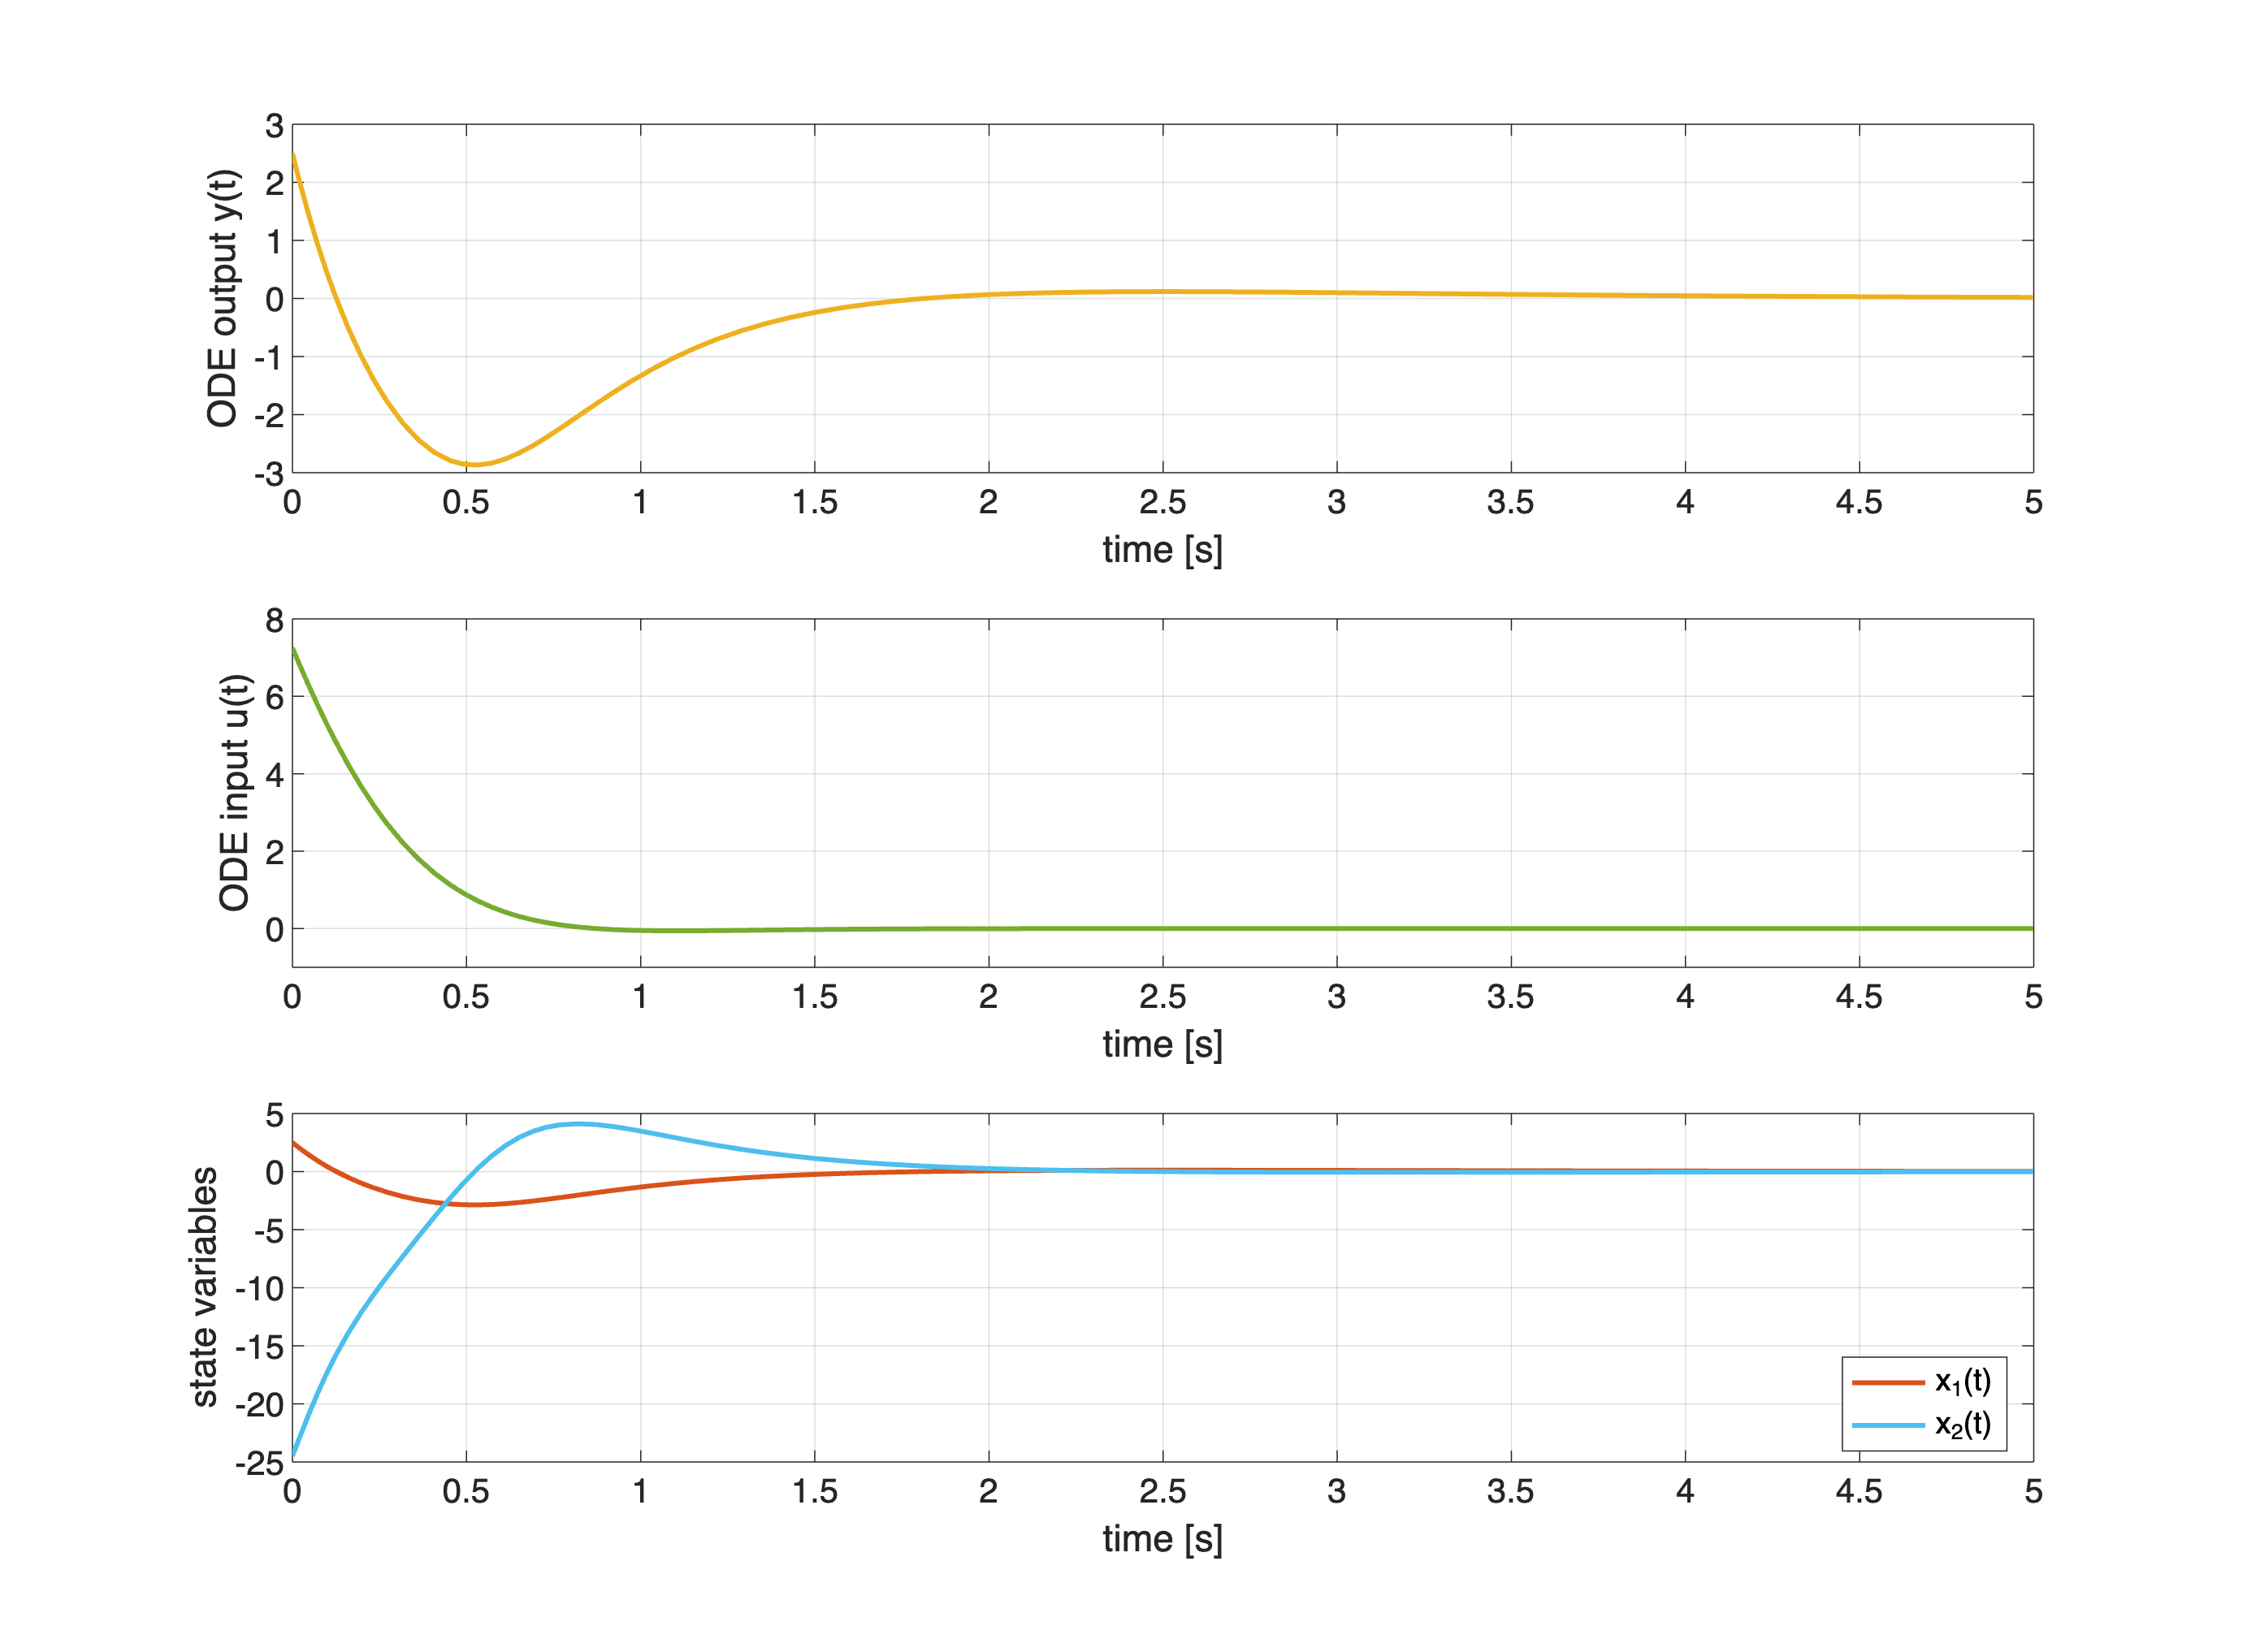

figure('Name','State-Space from ODE','Units','normalized','Position',[0.1, 0.1, 0.65, 0.85]);
h1 = subplot(3,1,1);
plot(t_stamps, y1, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]); % ODE output vs time 
xlabel('time [s]'); ylabel('ODE output y(t)'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);

h2 = subplot(3,1,2);
plot(t_stamps, u, 'LineWidth',2, 'Color',[0.4660 0.6740 0.1880]); % bioreactor outputs y_2 vs time
xlabel('time [s]'); ylabel('ODE input u(t)'); % labels on the plot axes
grid on;currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);

h3 = subplot(3,1,3);
plot(t_stamps, IO_x1, 'LineWidth',2, 'Color',[0.8500 0.3250 0.0980]); % state variable x_1
hold on;
plot(t_stamps, IO_x2, 'LineWidth',2, 'Color',[0.3010 0.7450 0.9330]); % state variable x_2
xlabel('time [s]'); ylabel('state variables'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('x_1(t)', 'x_2(t)', 'Location','best');
linkaxes([h1 h2 h3], 'x');

## Third Example: a Motor Drive with Flexible Shaft - Model Based on Conservation Balances

(Source:  Astrom K. J.. and Murray R. M., Feedback Systems, 2nd edition, v. 3.15 - available from [http://fbsbook.org](http://fbsbook.org) - Exercise 3.7)

Consider a system consisting of a motor driving two masses that are connected by a torsional spring, as shown in the following figure

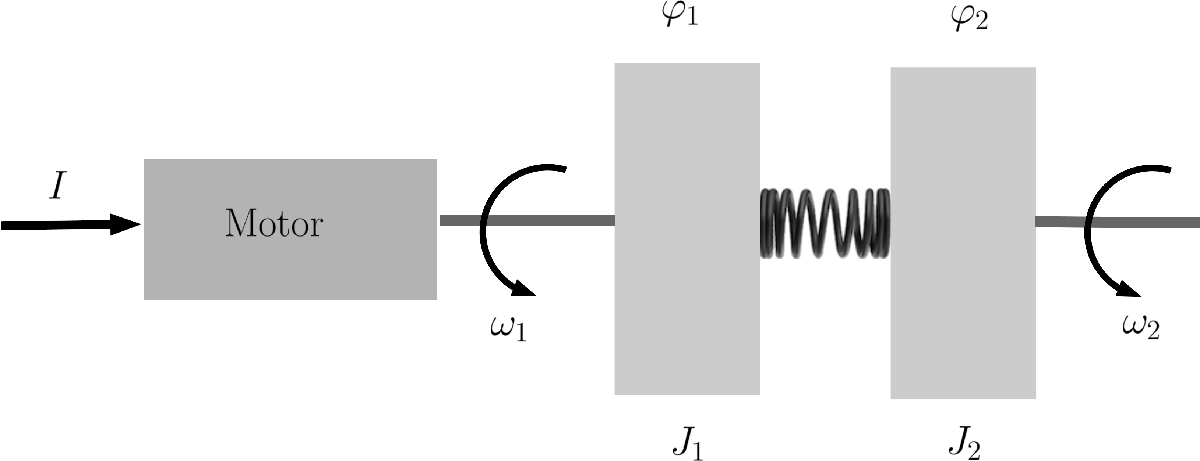

This system represents a motor with a flexible shaft, that drives a load. Let's consider as follows:

- The motor delivers a torque $T_M$ that is proportional to the current $I$: $T_M = k_I\,I$, where $k_I = 10 \;\text{[Nm/A]$.

- $J_1$ and $J_2$ represent the moments of inertia upstream and downstream of the flexible shaft, which is supposed to be massless.Assuume $J_1 = 5.0 \; \text{[kg}\,\text{m}^2\text{]}$, and $J_2 = 15.0 \; \text{[kg}\,\text{m}^2\text{]}$.

- The angles $\varphi_1$ and $\varphi_2$ are the rotation angles of the two masses; $\omega_1 = \frac{d\,\varphi_1}{d\,t}$ and $\omega_2 = \frac{d\,\varphi_2}{d\,t}$ are their velocities.

- The shaft stiffness is described by the coefficient $k$: $k = 3 \;\text{[Nm}\,\text{rad}^{-1}\text{]}$.

- The friction torque $T_F$ is proportional to the shaft velocity, through the damping coefficient $c$: $T_{F\,i} = c \,\omega_i\;,\quad i=1,\,2$ with $c = 2\;\text{[Nms}\,\text{rad}^{-1}\text{]}$.

- The torque $T_d$ is the disturbance torque applied at the end of the shaft: $T_d = 10.0 \cdot \mathbf{1}(t-5) \;\text{[Nm]}$, where, as usual, $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


- Apply the current $I$: $\bar I = 2\cdot 1(t) \;\text{[A]}$.

- Initial conditions: $\varphi_1(0) = 0\,,\quad \varphi_2(0) = 0 \,,\quad \omega_1(0) =0\,,\quad \omega_2(0) = 0$

The dynamics of the system can be described by the equations

 
$$\left\{ \begin{array}{rcl}
J_1 \, \frac{d^2\,\varphi_1}{d t^2} + c \left(\frac{d\,\varphi_1}{dt}- \frac{d\,\varphi_2}{dt}\right)+ k\left(\varphi_1-\varphi_2\right) &=& k_I I \\ \\
J_2 \, \frac{d^2\,\varphi_2}{d t^2} + c \left(\frac{d\,\varphi_2}{dt}- \frac{d\,\varphi_1}{dt}\right)+ k\left(\varphi_2-\varphi_1\right) &=& T_d
\end{array} \right. \qquad (+)$$


Let's derive a **state** **space** **model** for the system by introducing the (normalised) state variables


$$\begin{array}{rclcrcl}
x_1 &:=& \varphi_1 &\qquad& x_2&:=& \varphi_2 \\
x_3 &:=& \frac{\omega_1}{\omega_0} &\qquad& x_4 &:=& \frac{\omega_2}{\omega_0}
\end{array} \qquad \omega_0 := \sqrt{k\,\frac{J_1+J_2}{J_1\,J_2} }\qquad (++)$$


where $\omega_0$ is the undamped natural frequency of the system when the input $I$ is null.

Simulate the system dynamics in the time interval $\big[0,\,40 \big]$s.

### Cleaning the MATLAB Workspace

close all
clear
clc


### Assigning the System Parameters and the Input Configuration

k_I = 15.0; % N m/A          current-to-torque coefficient
c   = 2.0;  % N m rad^(-1)   damping coefficient
k   = 3.0;  % N m s rad^(-1) shaft stiffness coefficient
J1  = 15.0;  % kg m^2         inertia of the 1st mass
J2  = 5.0; % kg m^2         inertia of the 2nd mass

Om0 = sqrt(k*(J1+J2)/(J1*J2)); % the undamped natural frequency of the system when the input I is null

barI = 8.0; % A              input step amplitude
barTd = -80.0; % Nm           disturbance torque amplitude
barTd_delay = 0; % s         the disturbance torque is applied after barTd_delay seconds

#### Initial Condition 

x1_0 = 0; % initial value of the rotation angle x_1
x2_0 = 0; % initial value of the rotation angle x_2
x3_0 = 0; % initial value of the normalised angular speed x_3
x4_0 = 0; % initial value of the normalised angular speed x_4


#### Simulation Time Interval

T_start3 = 0.0; % starting time instant [s]
T_stop3 = 40.0; % end of the simulation  [s]

### Solving the ODE in MATLAB

By exploiting the definitions


$$\begin{array}{rclcrcl}
x_1 &:=& \varphi_1 &\qquad& x_2&:=& \varphi_2 \\
x_3 &:=& \frac{\omega_1}{\omega_0} &\qquad& x_4 &:=& \frac{\omega_2}{\omega_0}
\end{array} \qquad \omega_0 := \sqrt{k\,\frac{J_1+J_2}{J_1\,J_2} }\qquad (++)$$


we transform the second-order ODE system $(+)$ into the **system of two first-order Ordinary Differential Equations (ODEs)**. 


$$\left\{\begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\[0.5em]
\dot{x}_2(t) \\[0.5em]
\dot{x}_3(t) \\[0.5em]
\dot{x}_4(t) \\[0.5em]
\end{array} \right] &=& \left[ \begin{array}{c}
\omega_0 \cdot x_3(t) \\[0.5em]
\omega_0 \cdot x_4(t) \\[0.5em]
-\frac{k}{\omega_0\,J_1}\,\big(x_1(t)-x_2(t)\big)-\frac{c}{J_1}\,\big(x_3(t)-x_4(t) \big) + \frac{k_I}{\omega_0\,J_1}\;I(t) \\[0.5em]
-\frac{k}{\omega_0\,J_2}\,\big(x_2(t)-x_1(t)\big)-\frac{c}{J_2}\,\big(x_4(t)-x_3(t) \big) + \frac{1}{\omega_0\,J_2}\;T_d(t) \\[0.5em]
\end{array} \right] \\[0.75em] \\
I(t) &=& 2 \cdot 1(t) \\[0.5em]
T_d(t) &=&  10 \cdot 1(t-5)
\end{array} \right. \qquad (\triangle)$$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


#### The MATLAB Command ode

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a (vectorial) function (the solution of the ODE we are looking for) and $p$ is a vector of parameters.

Thus, since the ODEs $(**)$ are already a set of first-order ODEs (nonlinear ODEs), we can describe the ODEs set structure using the command `ode.`

#### Notation

It's not mandatory to obey the notation $\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$. Indeed, we will use a different notation for  IPVs, when they describe the evolution of a dynamic system (linear or nonlinear), keeping the notation $x$ for the state variables (the variables affected by the ODEs), and using the notation $y$ for the system's outputs. Thus, our default notation for an IVP is


$$\dot{x}(t) = f\big(t,\,x(t), p \big)\,,\quad \dot{x}(t) = \frac{d\,x(t)}{dt}$$


**Putting the ODEs in MATLAB**: Let's define the system of first-order ODEs with given initial conditions in MATLAB, using the command `ode`


$$\left\{\begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\[0.5em]
\dot{x}_2(t) \\[0.5em]
\dot{x}_3(t) \\[0.5em]
\dot{x}_4(t) \\[0.5em]
\end{array} \right] &=& \left[ \begin{array}{c}
\omega_0 \cdot x_3(t) \\[0.5em]
\omega_0 \cdot x_4(t) \\[0.5em]
-\frac{k}{\omega_0\,J_1}\,\big(x_1(t)-x_2(t)\big)-\frac{c}{J_1}\,\big(x_3(t)-x_4(t) \big) + \frac{k_I}{\omega_0\,J_1}\;I(t) \\[0.5em]
-\frac{k}{\omega_0\,J_2}\,\big(x_2(t)-x_1(t)\big)-\frac{c}{J_2}\,\big(x_4(t)-x_3(t) \big) + \frac{1}{\omega_0\,J_2}\;T_d(t) \\[0.5em]
\end{array} \right] \\[0.75em] \\
I(t) &=& 2 \cdot 1(t) \\[0.5em]
T_d(t) &=&  10 \cdot 1(t-5)
\end{array} \right. $$


where $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$


%
MotorShaft_ODE = ode; % let's initialise an ODE object
MotorShaft_ODE.Parameters   = [k_I, c, k, J1, ...
                                 J2, Om0, barI, barTd, ...
                                 barTd_delay];  % the parameters of the differential equation
% k_I = 10.0; % N m/A          current-to-torque coefficient
% c   = 2.0;  % N m rad^(-1)   damping coefficient
% k   = 3.0;  % N m s rad^(-1) shaft stiffness coefficient
% J1  = 5.0;  % kg m^2         inertia of the 1st mass
% J2  = 15.0; % kg m^2         inertia of the 2nd mass
% 
% Om0 = sqrt(k*(J1+J2)/(J1*J2)); % the undamped natural frequency of the system when the input I is null
% 
% barI = 2.0; % A              input step amplitude
% barTd = 10.0; % Nm           disturbance torque amplitude
% barTd_delay = 5; % s         the disturbance torque is applied after barTd_delay seconds


MotorShaft_ODE.InitialValue = [x1_0, x2_0, x3_0, x4_0];  % the initial conditions
% x1_0 = 0; % initial value of the rotation angle x_1
% x2_0 = 0; % initial value of the rotation angle x_2
% x3_0 = 0; % initial value of the normalised angular speed x_3
% x4_0 = 0; % initial value of the normalised angular speed x_4

MotorShaft_ODE.InitialTime = T_start3;   % starting time instant
                                         % the initial time instant of the solution, where 
                                         % the initial conditions are applied
% T_start3 = 0.0; % starting time instant [s]
% T_stop3 = 40.0; % end of the simulation  [s]

MotorShaft_ODE.ODEFcn = @MotorShaftODE; % MotorShaftODE is the MATLAB function describing the ODE, 
                                        % we would like to solve. 
                                        % The code of MotorShaftODE is at the end
                                        % of this live script.

#### Simulation of the System - Solving the ODE

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

For help on using the command `solve`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `solve` command computes the solution of the considered IVP `F` in the time interval `[t0, tf]`, returning the solution `S` at each time step chosen by the solver: 


S  = solve(MotorShaft_ODE, T_start3, T_stop3); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

MS_x = S.Solution; % the result of the IPv
t_stamps = S.Time;   % time instants corresponding to the solution samples 

MS_x1 = MS_x(1,:);
MS_x2 = MS_x(2,:);
MS_x3 = MS_x(3,:);
MS_x4 = MS_x(4,:);

Iu   = barI*ones(size(t_stamps));
Td_u = barTd*(t_stamps>=barTd_delay);


#### Retrieving and Showing the Result

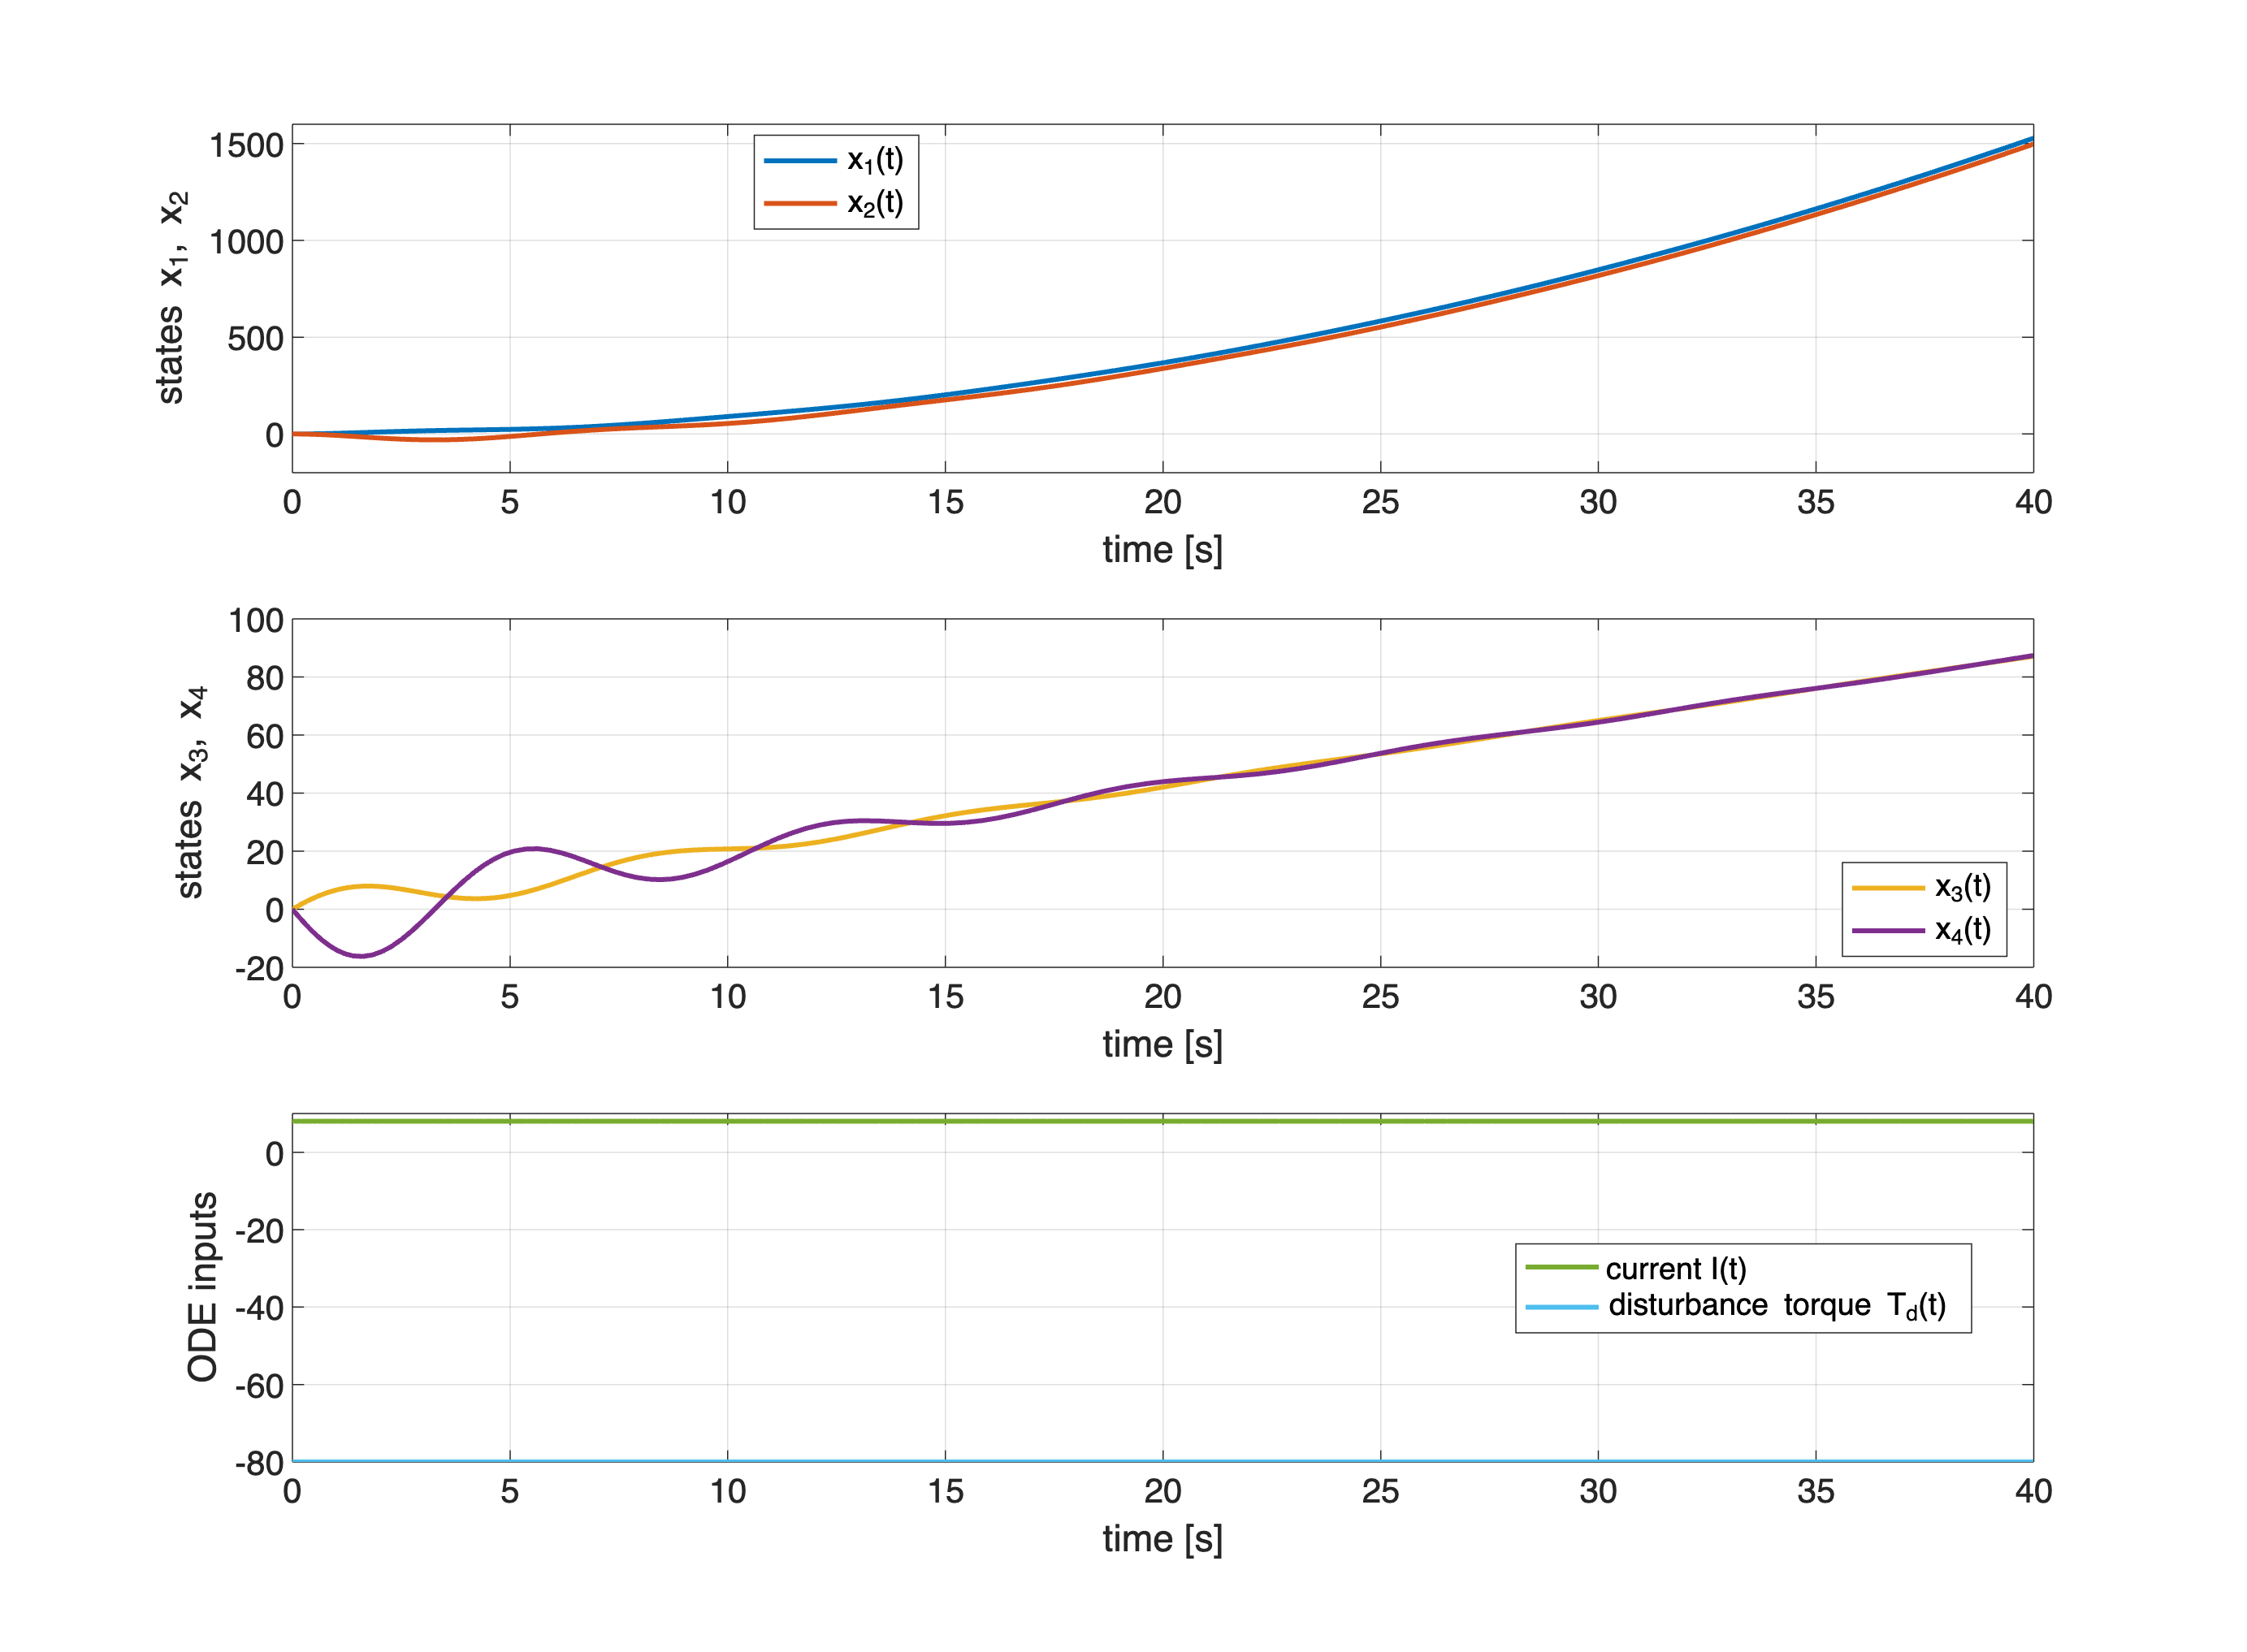

figure('Name','State-Space from ODE: a MotorDrive with Flexible Shaft',...
        'Units','normalized','Position',[0.1, 0.1, 0.65, 0.85]);
h1 = subplot(3,1,1);
plot(t_stamps, MS_x1, 'LineWidth',2); % ODE variables vs time 
hold on;
plot(t_stamps, MS_x2, 'LineWidth',2);
xlabel('time [s]'); ylabel('states x_1, x_2'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('x_1(t)', 'x_2(t)', 'Location','best');

h2 = subplot(3,1,2);
plot(t_stamps, MS_x3, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]);
hold on;
plot(t_stamps, MS_x4, 'LineWidth',2, 'Color',[0.4940 0.1840 0.5560]);
xlabel('time [s]'); ylabel('states x_3, x_4'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('x_3(t)', 'x_4(t)', 'Location','best');

h3 = subplot(3,1,3);
plot(t_stamps, Iu, 'LineWidth',2, 'Color',[0.4660 0.6740 0.1880]); % current I
hold on
plot(t_stamps, Td_u, 'LineWidth',2, 'Color',[0.3010 0.7450 0.9330]); % disturbance torque Td
xlabel('time [s]'); ylabel('ODE inputs'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('current I(t)', 'disturbance torque T_d(t)', 'Location','best');

linkaxes([h1 h2 h3], 'x');

## Some Proposals

Using what is shown in this live script, create the models and write the MATLAB code necessary to configure them, run the simulation and retrieve the results, for the examples proposed in the live script named [HandsON_StateSpaceDescription.mlx](matlab:open('./HandsON_StateSpaceDescription.mlx'))

## The Bioreactor Model: The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE system corresponding to


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& \left[\mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2\, x_2^2(t) + x_2(t)+K_1} \right] \cdot x_1(t) - \displaystyle \frac{x_1(t) \cdot  u(t)}{V} \\[0.5em]\\
\dot{x}_2(t) &=& -\displaystyle \frac{\left[\mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2 \,x_2^2(t) + x_2(t)+K_1} \right] \cdot x_1(t)}{Y} + \frac{\left(S_{F}-y_2(t)\right) \cdot u(t)}{V} \\[0.5em]\\
x_1(0) &=& x_{1,0} \\[0.5em]
x_2(0) &=& x_{2,0} \\
u(t) &=& U_M+u_A \cdot \Big[ \sin \big( 2\pi\,f_U\,t \big) \Big] \\
\end{array} \right. $$


The MATLAB function must provide the first derivative vector $\big[ \dot{x}_1(t),\;\dot{x}_2(t) \big]^{\top}$, given the values of the variables $x_1$ and $x_2$ at the current time instant $t$ and the parameters' values.


function dxdt = BioreactorODE(t, x, p)
    % BioR_ODE.Parameters   = [V, S_F, Y, muMAX, ...
    %                      K1, K2, U_M, u_A, T_u];  % the parameters of the differential equation
    % retrieving the parameters
    V_val     = p(1);
    SF_val    = p(2);
    Y_val     = p(3);
    muMAX_val = p(4);
    K1_val    = p(5);
    K2_val    = p(6);
    UM_val    = p(7);
    uA_val    = p(8);
    TU_val    = p(9);

    muVAL = muMAX_val*x(2)/(K2_val*(x(2)^2) + x(2) + K1_val);
    ut    = UM_val+uA_val*sin((2*pi)*(t/TU_val));
    dxdt = [muVAL*x(1)-(x(1)*ut)/V_val; ...
            -(muVAL*x(1))/Y_val+((SF_val-x(2))*ut)/V_val];

end % function

## The Nonlinear Input-Output Model: The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE system corresponding to


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& x_2(t) \\[0.5em]\\
\dot{x}_2(t) &=& -\alpha_1 x_2(t) -\alpha_0 x_1(t)\cdot \left[1+\gamma_1 x_1^2(t) \right] +\beta_0 \left[1+\gamma_2 x_1(t)\right]\cdot u(t) \\[0.5em]\\
x_1(0) &=& x_{1,0} \\[0.5em]
x_2(0) &=& x_{2,0} \\
u(t) &=& e^{-4\,t}\cdot \left[2.50 \sin(3\,t)-7.25 \cos(2\,t) \right]\cdot 1(t)
\end{array} \right. $$


The MATLAB function must provide the first derivative vector $\big[ \dot{x}_1(t),\;\dot{x}_2(t) \big]^{\top}$, given the values of the variables $x_1$ and $x_2$ at the current time instant $t$ and the parameters' values.

function dxdt = InOutODE(t, x, p)
   % IO_ODE.Parameters   = [alpha1, alpha0, gamma1, beta0, ...
   %                       gamma2, u_expT, u_sinA, u_sinO, ...
   %                       u_cosA, u_cosO];  % the parameters of the differential equation
   %  % retrieving the parameters
    alpha1_val = p(1);
    alpha0_val = p(2);
    gamma1_val = p(3);
    beta0_val  = p(4);
    gamma2_val = p(5);
    u_expT_val = p(6);
    u_sinA_val = p(7);
    u_sinO_val = p(8);
    u_cosA_val = p(9);
    u_cosO_val = p(10);

    ut    = exp(-t/u_expT_val)*(u_sinA_val*sin(u_sinO_val*t)+u_cosA_val*cos(u_cosO_val*t));
    dxdt = [ x(2); ...
            -alpha1_val*x(2)-alpha0_val*x(1)*(1+gamma1_val*(x(1)^2))+...
                beta0_val*(1+gamma2_val*x(1))*ut ];

end % function

## The Motor Drive with Flexible Shaft: The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE system corresponding to


$$\left\{\begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\[0.5em]
\dot{x}_2(t) \\[0.5em]
\dot{x}_3(t) \\[0.5em]
\dot{x}_4(t) \\[0.5em]
\end{array} \right] &=& \left[ \begin{array}{c}
\omega_0 \cdot x_3(t) \\[0.5em]
\omega_0 \cdot x_4(t) \\[0.5em]
-\frac{k}{\omega_0\,J_1}\,\big(x_1(t)-x_2(t)\big)-\frac{c}{J_1}\,\big(x_3(t)-x_4(t) \big) + \frac{k_I}{\omega_0\,J_1}\;I(t) \\[0.5em]
-\frac{k}{\omega_0\,J_2}\,\big(x_2(t)-x_1(t)\big)-\frac{c}{J_2}\,\big(x_4(t)-x_3(t) \big) + \frac{1}{\omega_0\,J_2}\;T_d(t) \\[0.5em]
\end{array} \right] \\[0.75em] \\
I(t) &=& 2 \cdot 1(t) \\[0.5em]
T_d(t) &=&  10 \cdot 1(t-5)
\end{array} \right. $$


The MATLAB function must provide the first derivative vector $\big[ \dot{x}_1(t),\;\dot{x}_2(t),\, \dot{x}_3(t),\;\dot{x}_4(t)\big]^{\top}$, given the values of the variables $x_1$, $x_2$, $x_3$ and $x_4$ at the current time instant $t$ and the parameters' values.

function dxdt = MotorShaftODE(t, x, p)
   % MotorShaft_ODE.Parameters   = [k_I, c, k, J1, ...
   %                               J2, Om0, barI, barTd, ...
   %                               barTd_delay];  % the parameters of the differential equation
   % %  % retrieving the parameters
    k_I_val = p(1);
    c_val = p(2);
    k_val = p(3);
    J1_val  = p(4);
    J2_val = p(5);
    Om0_val = p(6);
    barI_val = p(7);
    barTd_val = p(8);
    barTd_delay_val = p(9);

    kOm0J1 = k_val/(Om0_val*J1_val);
    kOm0J2 = k_val/(Om0_val*J2_val);
    cJ1    = c_val/J1_val;
    cJ2    = c_val/J2_val;
    kIOm0J1 = k_I_val/(Om0_val*J1_val);
    Om0J2_1 = 1/(Om0_val*J2_val);

    It   = barI_val;
    Td_t = barTd_val*(t>=barTd_delay_val);
    dxdt = [ Om0_val*x(3); ...
             Om0_val*x(4); ...
             -kOm0J1*(x(1)-x(2))-cJ1*(x(3)-x(4))+kIOm0J1*It; ...
             -kOm0J2*(x(2)-x(1))-cJ1*(x(4)-x(3))+Om0J2_1*Td_t     ];

end % function